%%parameters setting
clear all；clc;
N=1000; %The scale of the Graph
k=10; %The degree of a node
uff=0.6;ufn=0.8;unn=0.4;  %payoff matrix
U=[uff,ufn;ufn,unn];
alpha=0.09;      %weak-connection parameter
iteration_time=400;  
G_N=10;       %The Repeating Graphs of simulation
S_M=12;       %The Repeating times of simulation on one graph

Graphth_Result = zeros(G_N,iteration_time);      %To store the final result
tic
%make i graph results
for i = 1:G_N
        fprintf('The iteration i of  graph is %d\n',i);
        graph_sparse = createRandRegGraph(N, k);   %generate a sparse random regular graph
        graph_sparse=gather(graph_sparse);
        graph_matrix = full(graph_sparse);         %full the graph matrix    
        toc
        graph = graph_change(graph_matrix, N,k);
        toc
        Iteration_Results = zeros(S_M, iteration_time);
        toc
       
        parfor j = 1: S_M    
            fprintf('The iteration j time is %d\n',j);
            Iteration_Results(j, :) = simulate_im_over_regular_graph(U, graph, alpha, iteration_time, N,k);
        end
        Graphth_Result(i,:) = mean(Iteration_Results);
end

The iteration i of  graph is 1


createRandRegGraph() progress: edges=5000/10000


时间已过 2.904739 秒。


时间已过 2.915284 秒。


时间已过 2.915560 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 9
The iteration j time is 12
The iteration j time is 10
The iteration j time is 11


The iteration i of  graph is 2


createRandRegGraph() progress: edges=5000/10000


时间已过 7.642962 秒。


时间已过 7.646846 秒。


时间已过 7.647125 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 10
The iteration j time is 12
The iteration j time is 9
The iteration j time is 11


The iteration i of  graph is 3


createRandRegGraph() progress: edges=5000/10000


时间已过 12.035962 秒。


时间已过 12.038975 秒。


时间已过 12.039169 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 12
The iteration j time is 10
The iteration j time is 9
The iteration j time is 11


The iteration i of  graph is 4


createRandRegGraph() progress: edges=5000/10000


时间已过 16.322249 秒。


时间已过 16.325414 秒。


时间已过 16.325794 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 9
The iteration j time is 12
The iteration j time is 11
The iteration j time is 10


The iteration i of  graph is 5


createRandRegGraph() progress: edges=5000/10000


时间已过 20.629588 秒。


时间已过 20.633098 秒。


时间已过 20.633463 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 9
The iteration j time is 10
The iteration j time is 11
The iteration j time is 12


The iteration i of  graph is 6


createRandRegGraph() progress: edges=5000/10000


时间已过 25.163012 秒。


时间已过 25.165963 秒。


时间已过 25.166097 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 10
The iteration j time is 12
The iteration j time is 9
The iteration j time is 11


The iteration i of  graph is 7


createRandRegGraph() progress: edges=5000/10000


时间已过 29.511742 秒。


时间已过 29.514588 秒。


时间已过 29.514709 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 12
The iteration j time is 11
The iteration j time is 10
The iteration j time is 9


The iteration i of  graph is 8


createRandRegGraph() progress: edges=5000/10000


时间已过 33.952142 秒。


时间已过 33.955253 秒。


时间已过 33.955372 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 9
The iteration j time is 11
The iteration j time is 10
The iteration j time is 12


The iteration i of  graph is 9


createRandRegGraph() progress: edges=5000/10000


时间已过 38.324861 秒。


时间已过 38.328017 秒。


时间已过 38.328198 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 12
The iteration j time is 9
The iteration j time is 10
The iteration j time is 11


The iteration i of  graph is 10


createRandRegGraph() progress: edges=5000/10000


时间已过 42.841796 秒。


时间已过 42.844702 秒。


时间已过 42.844863 秒。


The iteration j time is 1
The iteration j time is 2
The iteration j time is 3
The iteration j time is 4
The iteration j time is 5
The iteration j time is 6
The iteration j time is 7
The iteration j time is 8
The iteration j time is 12
The iteration j time is 9
The iteration j time is 10
The iteration j time is 11


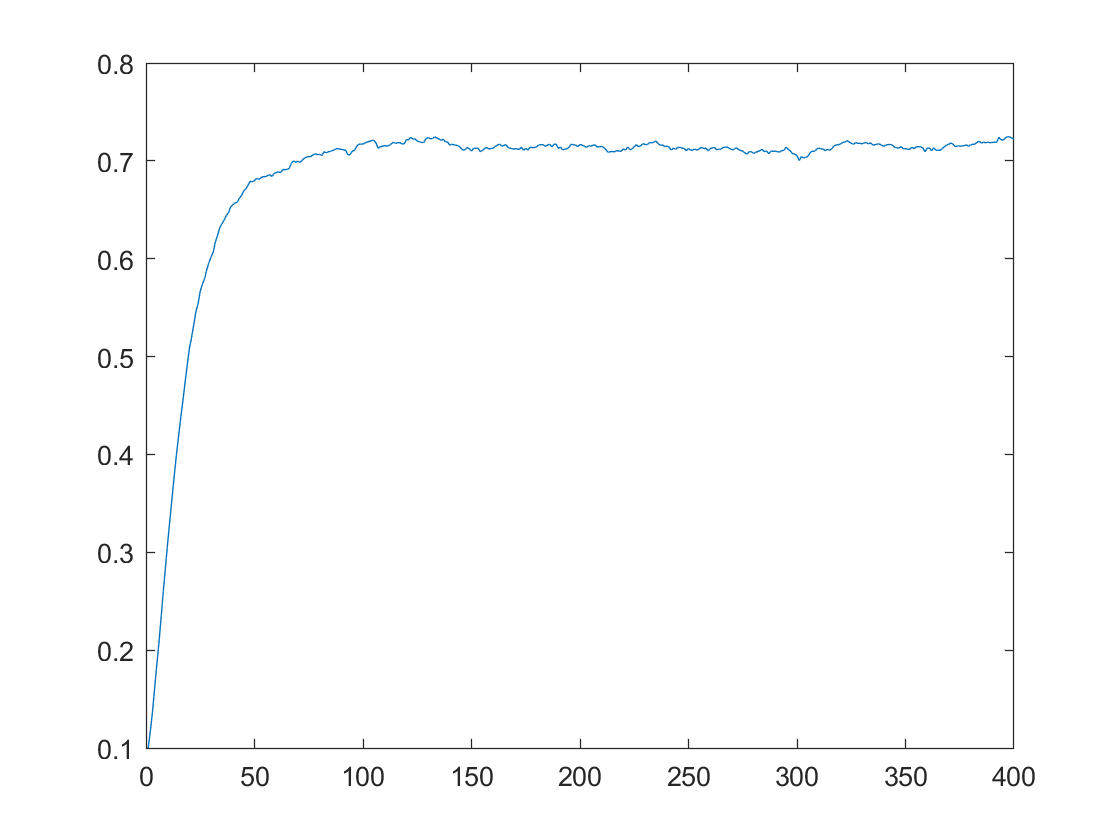


    Final_Results = mean(Graphth_Result);
    plot(Final_Results);